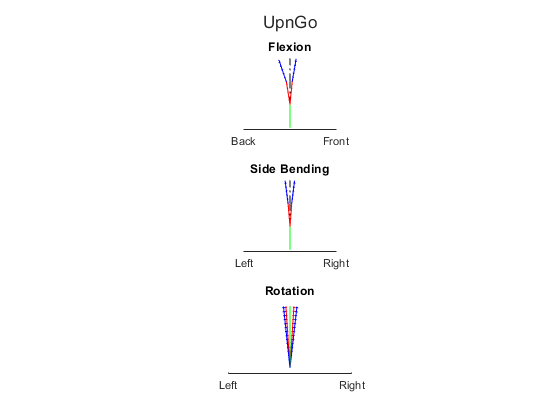

en={'Box_L';'Box_R';'ExBa_Cont';'ExBa_Ext';'ExBa_Flex';'Ext_L';'Ext_N';'Ext_R';
    'Flex';'Flex_L';'Flex_R';'Flex_box';'RotationL';'RotationR';'SideL';'SideR';
    'UpnGo'};
bL=nan(3,2,17); eL=nan(3,2,17);
bT=nan(3,2,17); eT=nan(3,2,17);
fnt=nan(1,17);
% This just for convenience so I don't have to have this ridiculously long
% filepath anywhere in the main body of the code
BasePath='C:\Users\gelde\Box\BACPAC Biomechanics and System Validation\Biomechanics MATLAB Subjects 1-30\Output\RoM\';
for ie=1:17 % Iterate through each exercise
    % Specify the exercise's I/O folder.
    IOFolder=strcat(BasePath,en{ie});
    cd(IOFolder); % Set I/O folder
    load(strcat('Combined_',en{ie},'.mat'))
    
    bL(:,:,ie)=rL; bT(:,:,ie)=rT;
    eL(:,:,ie)=Lstd/sqrt(fn); eT(:,:,ie)=Tstd/sqrt(fn); % Get standard errors for the exercise
    LS=Lstd*pi()/180/sqrt(fn); TS=Tstd*pi()/180/sqrt(fn); % Get standard error in radians for plotting
    fnt(ie)=fn;
    
    ltheta=[linspace(rL(1,1),rL(1,2),20);linspace(rL(2,1),rL(2,2),20);linspace(rL(3,1),rL(3,2),20)]*pi()/180;
    ttheta=[linspace(rT(1,1),rT(1,2),20);linspace(rT(2,1),rT(2,2),20);linspace(rT(3,1),rT(3,2),20)]*pi()/180;
    l1=[0,1;cos(pi()/2-ltheta(1,1)),sin(pi()/2-ltheta(1,1))+1]; 
    l2=[0,1;cos(pi()/2-ltheta(2,1)),sin(pi()/2-ltheta(2,1))+1]; 
    l3=[0,0;cos(pi()/2-ltheta(3,1)),sin(pi()/2-ltheta(3,1))]; 
    t1=[l1(2,:);l1(2,1)+cos(pi()/2-ttheta(1,1)),l1(2,2)+sin(pi()/2-ttheta(1,1))];
    t2=[l2(2,:);l2(2,1)+cos(pi()/2-ttheta(2,1)),l2(2,2)+sin(pi()/2-ttheta(2,1))];
    t3=[0,0;cos(pi()/2-ttheta(3,1)),sin(pi()/2-ttheta(3,1))];
    x1=[[0;0],l1(:,1),t1(:,1)]; x2=[[0;0],l2(:,1),t2(:,1)]; x3=[[0;0],-l3(:,1),-t3(:,1)];
    y1=[[0;1],l1(:,2),t1(:,2)]; y2=[[0;1],l2(:,2),t2(:,2)]; y3=[[0;1],l3(:,2),t3(:,2)];
    vx=[0,0,0;0,0,0]; vy=[0,1,2;1,2,3];
    hold off
    
    t=tiledlayout(3,1);
    
    nexttile
    sdx=zeros(5,2);    sdx(1:2,:)=[0,0; 0,cos(pi()/2-ltheta(1,1)-LS(1,1))];
    sdx(3,:)=[sdx(2,2),sdx(2,2)+cos(pi()/2-ttheta(1,1)-TS(1,1))];
    sdx(4:5,:)=[0,0; 0,cos(pi()/2-ltheta(1,1)+LS(1,1))];
    sdx(6,:)=[sdx(5,2),sdx(5,2)+cos(pi()/2-ttheta(1,1)+TS(1,1))];
    sdx=sdx';
    sdy=zeros(5,2);    sdy(1:2,:)=[0,1; 1,1+sin(pi()/2-ltheta(1,1)-LS(1,1))];
    sdy(3,:)=[sdy(2,2),sdy(2,2)+sin(pi()/2-ttheta(1,1)-TS(1,1))];
    sdy(4:5,:)=[0,1; 1,1+sin(pi()/2-ltheta(1,1)+LS(1,1))];
    sdy(6,:)=[sdy(5,2),sdy(5,2)+sin(pi()/2-ttheta(1,1)+TS(1,1))];
    sdy=sdy';
    plot(vx,vy,'k-.')
    hold on
    plot(sdx,sdy,':')
    plot(x1,y1)
    title 'Flexion';
    axis equal; box off
    ax1 = gca;                   % gca = get current axis
    ax1.YAxis.Visible = 'off';   % remove y-axis
    ylim([-.1,3.1]);
    xlim([-2,2]);
    xticks(xlim);
    xticklabels({'Back','Front'})
    colororder([0,1,0;1,0,0;0,0,1]);
    
    nexttile
    sdx=zeros(5,2);    sdx(1:2,:)=[0,0; 0,cos(pi()/2-ltheta(2,1)-LS(1,1))];
    sdx(3,:)=[sdx(2,2),sdx(2,2)+cos(pi()/2-ttheta(2,1)-TS(1,1))];
    sdx(4:5,:)=[0,0; 0,cos(pi()/2-ltheta(2,1)+LS(1,1))];
    sdx(6,:)=[sdx(5,2),sdx(5,2)+cos(pi()/2-ttheta(2,1)+TS(1,1))];
    sdx=sdx';
    sdy=zeros(5,2);    sdy(1:2,:)=[0,1; 1,1+sin(pi()/2-ltheta(2,1)-LS(1,1))];
    sdy(3,:)=[sdy(2,2),sdy(2,2)+sin(pi()/2-ttheta(2,1)-TS(1,1))];
    sdy(4:5,:)=[0,1; 1,1+sin(pi()/2-ltheta(2,1)+LS(1,1))];
    sdy(6,:)=[sdy(5,2),sdy(5,2)+sin(pi()/2-ttheta(2,1)+TS(1,1))];
    sdy=sdy';
    plot(vx,vy,'k-.')
    hold on
    plot(sdx,sdy,':')
    plot(x2,y2)
    title 'Side Bending'; 
    axis equal; box off
    ax1 = gca;                   % gca = get current axis
    ax1.YAxis.Visible = 'off';   % remove y-axis
    ylim([-.1,3.1]);
    xlim([-2,2]);
    xticks(xlim);
    xticklabels({'Left','Right'})
    colororder([0,1,0;1,0,0;0,0,1]);
    
    nexttile
    sdx=zeros(5,2);    sdx(1:2,:)=[0,0; 0,cos(pi()/2-ltheta(3,1)-LS(1,1))];
    sdx(3,:)=[0,cos(pi()/2-ttheta(3,1)-TS(1,1))];
    sdx(4:5,:)=[0,0; 0,cos(pi()/2-ltheta(3,1)+LS(1,1))];
    sdx(6,:)=[0,cos(pi()/2-ttheta(3,1)+TS(1,1))];
    sdx=-sdx';
    sdy=zeros(5,2);    sdy(1:2,:)=[0,1; 0,sin(pi()/2-ltheta(3,1)-LS(1,1))];
    sdy(3,:)=[0,sin(pi()/2-ttheta(3,1)-TS(1,1))];
    sdy(4:5,:)=[0,1; 0,sin(pi()/2-ltheta(3,1)+LS(1,1))];
    sdy(6,:)=[0,sin(pi()/2-ttheta(3,1)+TS(1,1))];
    sdy=sdy';
    vx=[0,0,0;0,0,0]; vy=[0,1/3,2/3;1/3,2/3,1];
    plot(vx,vy,'k-.')
    hold on
    plot(sdx,sdy,':')
    plot(x3,y3)
    title 'Rotation'; 
    axis equal; box off
    ax1 = gca;                   % gca = get current axis
    ax1.YAxis.Visible = 'off';   % remove y-axis
    ylim([-.1,1.1]);
    xlim([-1,1]);
    xticks(xlim);
    xticklabels({'Left','Right'})
    colororder([0,1,0;1,0,0;0,0,1]);
    
    i=20;
    l1=[0,1;cos(pi()/2-ltheta(1,i)),sin(pi()/2-ltheta(1,i))+1]; 
    l2=[0,1;cos(pi()/2-ltheta(2,i)),sin(pi()/2-ltheta(2,i))+1]; 
    l3=[0,0;cos(pi()/2-ltheta(3,i)),sin(pi()/2-ltheta(3,i))]; 
    t1=[l1(2,:);l1(2,1)+cos(pi()/2-ttheta(1,i)),l1(2,2)+sin(pi()/2-ttheta(1,i))];
    t2=[l2(2,:);l2(2,1)+cos(pi()/2-ttheta(2,i)),l2(2,2)+sin(pi()/2-ttheta(2,i))];
    t3=[0,0;cos(pi()/2-ttheta(3,i)),sin(pi()/2-ttheta(3,i))];
    x1=[[0;0],l1(:,1),t1(:,1)]; x2=[[0;0],l2(:,1),t2(:,1)]; x3=[[0;0],-l3(:,1),-t3(:,1)];
    y1=[[0;1],l1(:,2),t1(:,2)]; y2=[[0;1],l2(:,2),t2(:,2)]; y3=[[0;1],l3(:,2),t3(:,2)];
    
    nexttile(1)
    sdx=zeros(5,2);    sdx(1:2,:)=[0,0; 0,cos(pi()/2-ltheta(1,i)-LS(1,1))];
    sdx(3,:)=[sdx(2,2),sdx(2,2)+cos(pi()/2-ttheta(1,i)-TS(1,1))];
    sdx(4:5,:)=[0,0; 0,cos(pi()/2-ltheta(1,i)+LS(1,1))];
    sdx(6,:)=[sdx(5,2),sdx(5,2)+cos(pi()/2-ttheta(1,i)+TS(1,1))];
    sdx=sdx';
    sdy=zeros(5,2);    sdy(1:2,:)=[0,1; 1,1+sin(pi()/2-ltheta(1,i)-LS(1,1))];
    sdy(3,:)=[sdy(2,2),sdy(2,2)+sin(pi()/2-ttheta(1,i)-TS(1,1))];
    sdy(4:5,:)=[0,1; 1,1+sin(pi()/2-ltheta(1,i)+LS(1,1))];
    sdy(6,:)=[sdy(5,2),sdy(5,2)+sin(pi()/2-ttheta(1,i)+TS(1,1))];
    sdy=sdy';
    plot(sdx,sdy,':')
    plot(x1,y1)
    
    nexttile(2)
    sdx=zeros(5,2);    sdx(1:2,:)=[0,0; 0,cos(pi()/2-ltheta(2,i)-LS(1,1))];
    sdx(3,:)=[sdx(2,2),sdx(2,2)+cos(pi()/2-ttheta(2,i)-TS(1,1))];
    sdx(4:5,:)=[0,0; 0,cos(pi()/2-ltheta(2,i)+LS(1,1))];
    sdx(6,:)=[sdx(5,2),sdx(5,2)+cos(pi()/2-ttheta(2,i)+TS(1,1))];
    sdx=sdx';
    sdy=zeros(5,2);    sdy(1:2,:)=[0,1; 1,1+sin(pi()/2-ltheta(2,i)-LS(1,1))];
    sdy(3,:)=[sdy(2,2),sdy(2,2)+sin(pi()/2-ttheta(2,i)-TS(1,1))];
    sdy(4:5,:)=[0,1; 1,1+sin(pi()/2-ltheta(2,i)+LS(1,1))];
    sdy(6,:)=[sdy(5,2),sdy(5,2)+sin(pi()/2-ttheta(2,i)+TS(1,1))];
    sdy=sdy';
    plot(sdx,sdy,':')
    plot(x2,y2)
    
    nexttile(3)
    sdx=zeros(5,2);    sdx(1:2,:)=[0,0; 0,cos(pi()/2-ltheta(3,i)-LS(1,1))];
    sdx(3,:)=[0,cos(pi()/2-ttheta(3,i)-TS(1,1))];
    sdx(4:5,:)=[0,0; 0,cos(pi()/2-ltheta(3,i)+LS(1,1))];
    sdx(6,:)=[0,cos(pi()/2-ttheta(3,i)+TS(1,1))];
    sdx=-sdx';
    sdy=zeros(5,2);    sdy(1:2,:)=[0,1; 0,sin(pi()/2-ltheta(3,i)-LS(1,1))];
    sdy(3,:)=[0,sin(pi()/2-ttheta(3,i)-TS(1,1))];
    sdy(4:5,:)=[0,1; 0,sin(pi()/2-ltheta(3,i)+LS(1,1))];
    sdy(6,:)=[0,sin(pi()/2-ttheta(3,i)+TS(1,1))];
    sdy=sdy';
    plot(sdx,sdy,':')
    plot(x3,y3)
    
    title(t,en{ie},'Interpreter','none')
    hold off
    print('-r300',strcat('RoM_KinFig_h_',en{ie}),'-dpng');
    clearvars -except 'BasePath' 'en' 'ie' 'bL' 'bT' 'eL' 'eT' 'fnt'
end

IOFolder=BasePath;
cd(IOFolder); % Set Output folder

colororder([1,0,0;0,0,1]);
%% LUMBAR
x=1:17;
x2=[1:17,1:17];
y1=[bL(1,:,1);bL(1,:,2);bL(1,:,3);bL(1,:,4);bL(1,:,5);bL(1,:,6);bL(1,:,7);bL(1,:,8)
    bL(1,:,9);bL(1,:,10);bL(1,:,11);bL(1,:,12);bL(1,:,13);bL(1,:,14);bL(1,:,15);bL(1,:,16)
    bL(1,:,17)];
ye1=[y1(:,1)',y1(:,2)'];
y2=[bL(2,:,1);bL(2,:,2);bL(2,:,3);bL(2,:,4);bL(2,:,5);bL(2,:,6);bL(2,:,7);bL(2,:,8)
    bL(2,:,9);bL(2,:,10);bL(2,:,11);bL(2,:,12);bL(2,:,13);bL(2,:,14);bL(2,:,15);bL(2,:,16)
    bL(2,:,17)];
ye2=[y2(:,1)',y2(:,2)'];
y3=[bL(3,:,1);bL(3,:,2);bL(3,:,3);bL(3,:,4);bL(3,:,5);bL(3,:,6);bL(3,:,7);bL(3,:,8)
    bL(3,:,9);bL(3,:,10);bL(3,:,11);bL(3,:,12);bL(3,:,13);bL(3,:,14);bL(3,:,15);bL(3,:,16)
    bL(3,:,17)];
ye3=[y3(:,1)',y3(:,2)'];
e1=[eL(1,:,1);eL(1,:,2);eL(1,:,3);eL(1,:,4);eL(1,:,5);eL(1,:,6);eL(1,:,7);eL(1,:,8)
    eL(1,:,9);eL(1,:,10);eL(1,:,11);eL(1,:,12);eL(1,:,13);eL(1,:,14);eL(1,:,15);eL(1,:,16)
    eL(1,:,17)];
e1=[e1(:,1)',e1(:,2)'];
e2=[eL(2,:,1);eL(2,:,2);eL(2,:,3);eL(2,:,4);eL(2,:,5);eL(2,:,6);eL(2,:,7);eL(2,:,8)
    eL(2,:,9);eL(2,:,10);eL(2,:,11);eL(2,:,12);eL(2,:,13);eL(2,:,14);eL(2,:,15);eL(2,:,16)
    eL(2,:,17)];
e2=[e2(:,1)',e2(:,2)'];
e3=[eL(3,:,1);eL(3,:,2);eL(3,:,3);eL(3,:,4);eL(3,:,5);eL(3,:,6);eL(3,:,7);eL(3,:,8)
    eL(3,:,9);eL(3,:,10);eL(3,:,11);eL(3,:,12);eL(3,:,13);eL(3,:,14);eL(3,:,15);eL(3,:,16)
    eL(3,:,17)];
e3=[e3(:,1)',e3(:,2)'];
t=tiledlayout(3,1);
title(t,'Lumbar Segment Ranges of Motion (relative to sacrum)')
nexttile
bar(x,y1,'stacked');
title 'Flexion (rotation in the sagittal plane)'
xticks(x);
set(gca,'TickLabelInterpreter','none')
xticklabels(en')
ylabel 'Angular Deflection (degrees)'
hold on
er = errorbar(x2,ye1,e1);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off
nexttile

bar(x,y2,'stacked');
title 'Side-Bending (rotation in the frontal plane)'
xticks(x);
set(gca,'TickLabelInterpreter','none')
xticklabels(en')
ylabel 'Angular Deflection (degrees)'
hold on
er = errorbar(x2,ye2,e2);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off
nexttile

bar(x,y3,'stacked');
title 'Rotation (rotation in the transverse plane)'
xticks(x);
set(gca,'TickLabelInterpreter','none')
xticklabels(en')
ylabel 'Angular Deflection (degrees)'
hold on
er = errorbar(x2,ye3,e3);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off

% print('-r300',strcat('RoM_BarChartL','-dpng');

IOFolder=BasePath;
cd(IOFolder); % Set Output folder

colororder([1,0,0;0,0,1]);
%% THORACIC
x=1:17;
x2=[1:17,1:17];
y1=[bT(1,:,1);bT(1,:,2);bT(1,:,3);bT(1,:,4);bT(1,:,5);bT(1,:,6);bT(1,:,7);bT(1,:,8)
    bT(1,:,9);bT(1,:,10);bT(1,:,11);bT(1,:,12);bT(1,:,13);bT(1,:,14);bT(1,:,15);bT(1,:,16)
    bT(1,:,17)];
ye1=[y1(:,1)',y1(:,2)'];
y2=[bT(2,:,1);bT(2,:,2);bT(2,:,3);bT(2,:,4);bT(2,:,5);bT(2,:,6);bT(2,:,7);bT(2,:,8)
    bT(2,:,9);bT(2,:,10);bT(2,:,11);bT(2,:,12);bT(2,:,13);bT(2,:,14);bT(2,:,15);bT(2,:,16)
    bT(2,:,17)];
ye2=[y2(:,1)',y2(:,2)'];
y3=[bT(3,:,1);bT(3,:,2);bT(3,:,3);bT(3,:,4);bT(3,:,5);bT(3,:,6);bT(3,:,7);bT(3,:,8)
    bT(3,:,9);bT(3,:,10);bT(3,:,11);bT(3,:,12);bT(3,:,13);bT(3,:,14);bT(3,:,15);bT(3,:,16)
    bT(3,:,17)];
ye3=[y3(:,1)',y3(:,2)'];
e1=[eT(1,:,1);eT(1,:,2);eT(1,:,3);eT(1,:,4);eT(1,:,5);eT(1,:,6);eT(1,:,7);eT(1,:,8)
    eT(1,:,9);eT(1,:,10);eT(1,:,11);eT(1,:,12);eT(1,:,13);eT(1,:,14);eT(1,:,15);eT(1,:,16)
    eT(1,:,17)];
e1=[e1(:,1)',e1(:,2)'];
e2=[eT(2,:,1);eT(2,:,2);eT(2,:,3);eT(2,:,4);eT(2,:,5);eT(2,:,6);eT(2,:,7);eT(2,:,8)
    eT(2,:,9);eT(2,:,10);eT(2,:,11);eT(2,:,12);eT(2,:,13);eT(2,:,14);eT(2,:,15);eT(2,:,16)
    eT(2,:,17)];
e2=[e2(:,1)',e2(:,2)'];
e3=[eT(3,:,1);eT(3,:,2);eT(3,:,3);eT(3,:,4);eT(3,:,5);eT(3,:,6);eT(3,:,7);eT(3,:,8)
    eT(3,:,9);eT(3,:,10);eT(3,:,11);eT(3,:,12);eT(3,:,13);eT(3,:,14);eT(3,:,15);eT(3,:,16)
    eT(3,:,17)];
e3=[e3(:,1)',e3(:,2)'];
t=tiledlayout(3,1);
title(t,'Thoracic Segment Ranges of Motion (relative to sacrum)')
nexttile
b1=bar(x,y1,'stacked');
title 'Flexion (rotation in the sagittal plane)'
xticks(x);
set(gca,'TickLabelInterpreter','none')
xticklabels(en')
ylabel 'Angular Deflection (degrees)'
hold on
er = errorbar(x2,ye1,e1);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off
nexttile

b2=bar(x,y2,'stacked');
title 'Side-Bending (rotation in the frontal plane)'
xticks(x);
set(gca,'TickLabelInterpreter','none')
xticklabels(en')
ylabel 'Angular Deflection (degrees)'
hold on
er = errorbar(x2,ye2,e2);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off
nexttile

b3=bar(x,y3,'stacked');
title 'Rotation (rotation in the transverse plane)'
xticks(x);
set(gca,'TickLabelInterpreter','none')
xticklabels(en')
ylabel 'Angular Deflection (degrees)'
hold on
er = errorbar(x2,ye3,e3);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off

% print('-r300',strcat('RoM_BarChartT''-dpng');